m2 = 0.04;
l2 = 0.2;
% m2 = 0.065;
% l2 = 0.115;

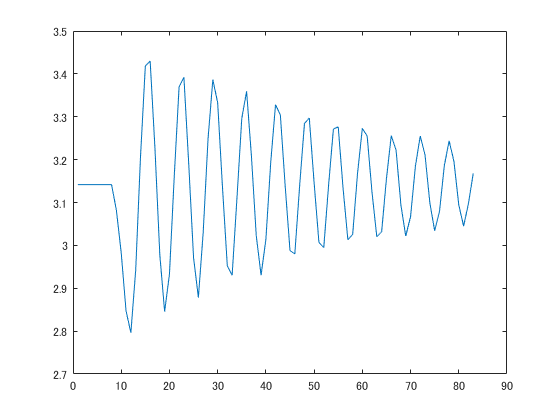

time = out.time;

theta1 = out.theta1;
theta2 = out.theta2;

figure(4);
plot(time,theta2);
hold on
stairs(double(sh2pc_step_table.TMStamp - sh2pc_step_table.TMStamp(1))/1000, double(sh2pc_step_table.ArmAngle-arm_s_ini)*2*pi/ARM + pi);
hold off

Invalid operation. Object must be connected to the serial port.

figure(2);
plot(time,theta1);
hold on
stairs((sh2pc_step_table.TMStamp - sh2pc_step_table.TMStamp(1))/1000, double(sh2pc_step_table.BaseAngle)*2*pi/BASE);
hold off

figure(2);
plot(time,theta1);
hold on
stairs(double(sh2pc2table.TMStamp(80:150) - sh2pc2table.TMStamp(80))/1000, double(sh2pc2table.BaseAngle(80:150))*2*pi/BASE);
hold off
stairs(double(sh2pc2table.TMStamp(80:150) - sh2pc2table.TMStamp(80))/1000, double(sh2pc2table.BaseAngle(80:150))*2*pi/BASE);

%%% ステップ入力の場合の実機出力とシミュレーション結果を比較する
% 初期値取得
for i = 1 : 100
    tic;
    
    write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    sh2pc_step0(i) = sci_read_with_decode_using_checksum(seri);    
    
    pause(SAMPLING_TIME - toc);
end
sh2pc_step0(100).ArmAngle
sh2pc_step0(100).TMStamp

pause(5);
for i = 1 : 300 
    disp(i)
    
    if i <= 100
        
        write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
        
    else
        
        write(seri, typecast(swapbytes(0.5), 'uint8'), 'uint8');
        
    end

    sh2pc_step(i) = sci_read_with_decode_using_checksum(seri);
end

%write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');

clear sh2pc_step sh2pc_step0 sh2pc_step_table;

% 棒の初期角度=arm_s_ini
arm_s_ini = sh2pc_step0(100).ArmAngle;
sh2pc_step_table=struct2table(sh2pc_step);
figure(4);
stairs(double(sh2pc_step_table.BaseAngle)*360/BASE);
stairs((sh2pc_step_table.TMStamp - sh2pc_step_table.TMStamp(1))/1000, double(sh2pc_step_table.BaseAngle)*360/BASE);
% stairs(sh2pc_step_table.BaseAngle);
figure(2);
stairs(double(sh2pc_step_table.ArmAngle-arm_s_ini)*2*pi/ARM + pi);

clear time theta1 theta2

%% 動摩擦係数を求める

% 角速度
d_base_idx = length(t(80:120));
d_baseangle(1) = (-3*y4(80) + 4*y4(81) -y4(82)) / (double(t(82) - t(80))/1000);

for i = 2:length(t(80:120))-1
    
    d_baseangle(i) = (y4(82+i) - y4(82-i)) / (double(t(82+i) - t(82-i))/1000);
    
end

%d_baseangle(d_base_idx) =  (y4(d_base_idx-2) - 4*y4(d_base_idx-1) + 3*y4(d_base_idx)) / (double(t(d_base_idx) - t(d_base_idx-2))/1000);

% 角加速度
dd_baseangle(1) = (-3*d_baseangle(1) + 4*d_baseangle(2) - d_baseangle(3)) / (double(t(82) - t(80))/1000);

for i = 2:d_base_idx-2
    
    dd_baseangle(i) = (d_baseangle(i+1) - d_baseangle(i-1)) / (double(t(82+i) - t(82-i))/1000);
    
end

dd_baseangle(d_base_idx-1) = (d_baseangle(d_base_idx-3) - 4*d_baseangle(d_base_idx-2) + 3*d_baseangle(d_base_idx-1)) / (double(t(d_base_idx-1) - t(d_base_idx-3))/1000);

% 縦ベクトル化
b_time = double(t(80:119) - t(80));
%b_time = b_time';

b_theta = y4(80:119);
%b_theta = b_theta';
d_baseangle = (d_baseangle(1:40))';
dd_baseangle = dd_baseangle';

b_volt = (volt(80:119))';

clear d_baseangle dd_baseangle b_time b_theta b_volt 

% %%% 先頭と末尾の要素を外す
% % 角速度
% d_base_idx = length(t(80:120));
% %d_baseangle(1) = (-3*y4(80) + 4*y4(81) -y4(82)) / (double(t(82) - t(80))/1000);
% 
% for i = 2:length(t(80:120))-1
%     
%     d_baseangle(i-1) = (y4(82+i) - y4(82-i)) / (double(t(82+i) - t(82-i))/1000);
%     
% end
% 
% %d_baseangle(d_base_idx) =  (-3*y4(80) + 4*y4(81) -y4(82)) / (double(t(82) - t(80))/1000);
% 
% % 角加速度
% %dd_baseangle(1) = (-3*d_baseangle(1) + 4*d_baseangle(2) - d_baseangle(3)) / (double(t(82) - t(80))/1000);
% 
% for i = 2:d_base_idx-3
%     
%     dd_baseangle(i-1) = (d_baseangle(i+1) - d_baseangle(i-1)) / (double(t(82+i) - t(82-i))/1000);
%     
% end
% 
% %dd_baseangle(d_base_idx-1) = (d_baseangle(d_base_idx-3) - 4*d_baseangle(d_base_idx-2) + 3*d_baseangle(d_base_idx-1)) / (double(t(d_base_idx-1) - t(d_base_idx-3))/1000);

% % 縦ベクトル化
% b_time = double(t(82:118) - t(82));
% b_time = b_time';
% 
% b_theta = y4(80:119);
% b_theta = b_theta';
% d_baseangle = d_baseangle';
% dd_baseangle = dd_baseangle';
% 
% b_volt = (volt(80:119))';

%simulinkでローパスフィルタを通す
Tf1 = 0.015;
Ms1 = out.Ms1;
Mfs1 = out.Mfs1;
Ns1 = out.Ns1;
Nfs1 = out.Nfs1;

% 動摩擦係数導出
p1_sgn = inv(Mfs1'*Mfs1)*Mfs1'*Nfs1;
p1_sgn = inv(Ms1'*Ms1)*Ms1'*Ns1;

clear out Tf1 Ms1 Mfs1 Ns1 Nfs1 p1_sgn

%----------------------------------------
%% simulinkのモデルにステップ入力
y4 = double(sh2pc2table.BaseAngle)*2*pi/BASE;
stairs(double( t(80:120)-t(80) )/1000, y4(80:120));
hold on
plot(time(1:101), theta1(1:101));
hold off

%% 入力無し場合の棒の角度プロット
% 初期角度 0.4357 + pi
y3 = (double(sh2pc3Table.ArmAngle)-809)*2*pi/1024 + pi;
stairs(double(t2(865:1510)-t2(865))/1000, y3(865:1510));
hold on
plot(time,theta2);
hold off